# Localization

See the video;

https://es.mathworks.com/videos/understanding-kalman-filters-part-3-optimal-state-estimator--1490710645421.html

format compact
close all
clear
clc

## Dead reckoning = stimate the robot pose 

### Modeling the vehicle

V = diag([0.02, 0.5*pi/180].^2);

veh = Bicycle('covar', V)

veh = 
Bicycle object                      
  L=1, steer.max=0.5, accel.max=Inf 
  Superclass: Vehicle               
    max speed=1, dT=0.1, nhist=0    
    V=(0.0004, 7.61544e-05)         
    configuration: x=0, y=0, theta=0



randinit
vel=1 % velocity

vel = 1

gamma=0.3 % steering angle

gamma = 0.3000

odo = veh.step(vel, gamma)

odo =     0.1108    0.0469


### Pose without Noise

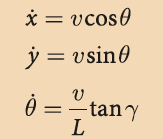


$$\theta^˙ =\frac{v}{L}\mathrm{tan}\gamma$$
 
$$\longrightarrow \theta =\int_{t_k }^{t_{k+1} } \theta^˙ \mathrm{dt}={\theta^˙ t}_s$$


Using the RTB demo

next_pose=veh.x'

next_pose =     0.1000         0    0.0309


By hand

theta_d=vel*tan(gamma)/veh.L

theta_d = 0.3093

theta=theta_d*veh.dt

theta = 0.0309

next_pose_h=transl(vel*veh.dt,0,0)*trotz(theta)

next_pose_h =     0.9995   -0.0309         0    0.1000
    0.0309    0.9995         0         0
         0         0    1.0000         0
         0         0         0    1.0000


theta_h=tr2rpy(next_pose_h)

theta_h =          0         0    0.0309


### With noise

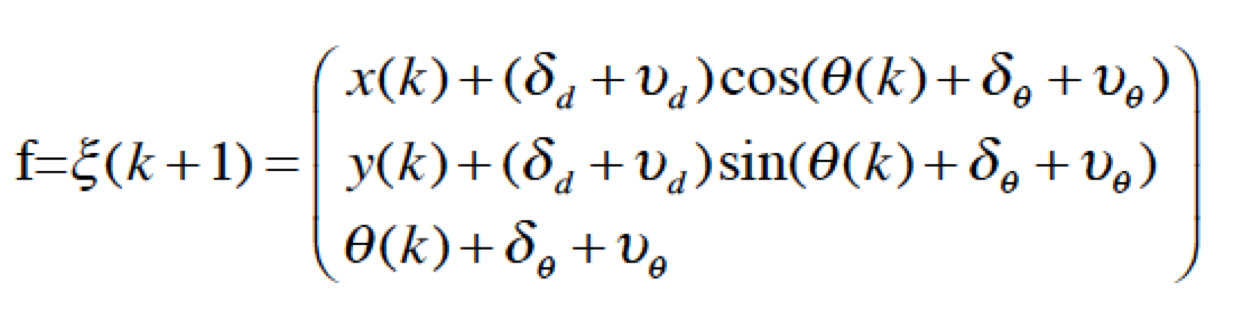

Using the RTB method

veh.f([0 0 0], odo)

ans =     0.1106    0.0052    0.0469


By hand

x_next=odo(1)*cos(0+odo(2))

x_next = 0.1106

y_next=odo(1)*sin(0+odo(2))

y_next = 0.0052

theta_next=odo(2)

theta_next = 0.0469

### Adding a driver and running the simulation 

The vehicle is in a [-10 10 -10 10] enviroment and it move using go to point 

veh.add_driver( RandomPath(10) )

Running the simulation which repeatedly calls the step method and maintains a history of the true state of the  vehicle. Be patient

%% See the demo  first of the 'rtbdemo'
veh.run(1000) % be patient in the mlx there is no animation

ans =     0.1000         0   -0.0546
    0.1999   -0.0055   -0.1093
    0.2993   -0.0164   -0.1639
    0.3979   -0.0327   -0.2185
    0.4955   -0.0544   -0.2732
    0.5918   -0.0813   -0.3278
    0.6865   -0.1135   -0.3824
    0.7793   -0.1508   -0.4370
    0.8699   -0.1932   -0.4917
    0.9580   -0.2404   -0.5463


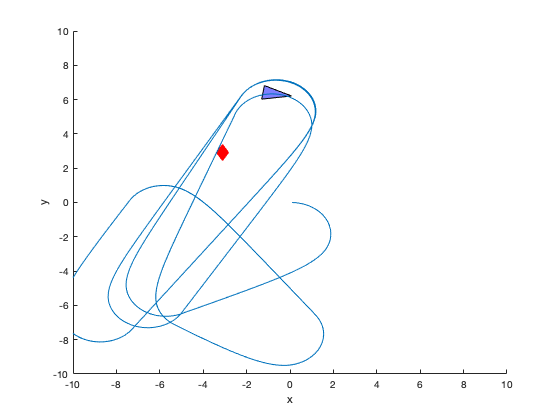

plot(veh.x_hist(:,1), veh.x_hist(:,2))

### Estimating pose

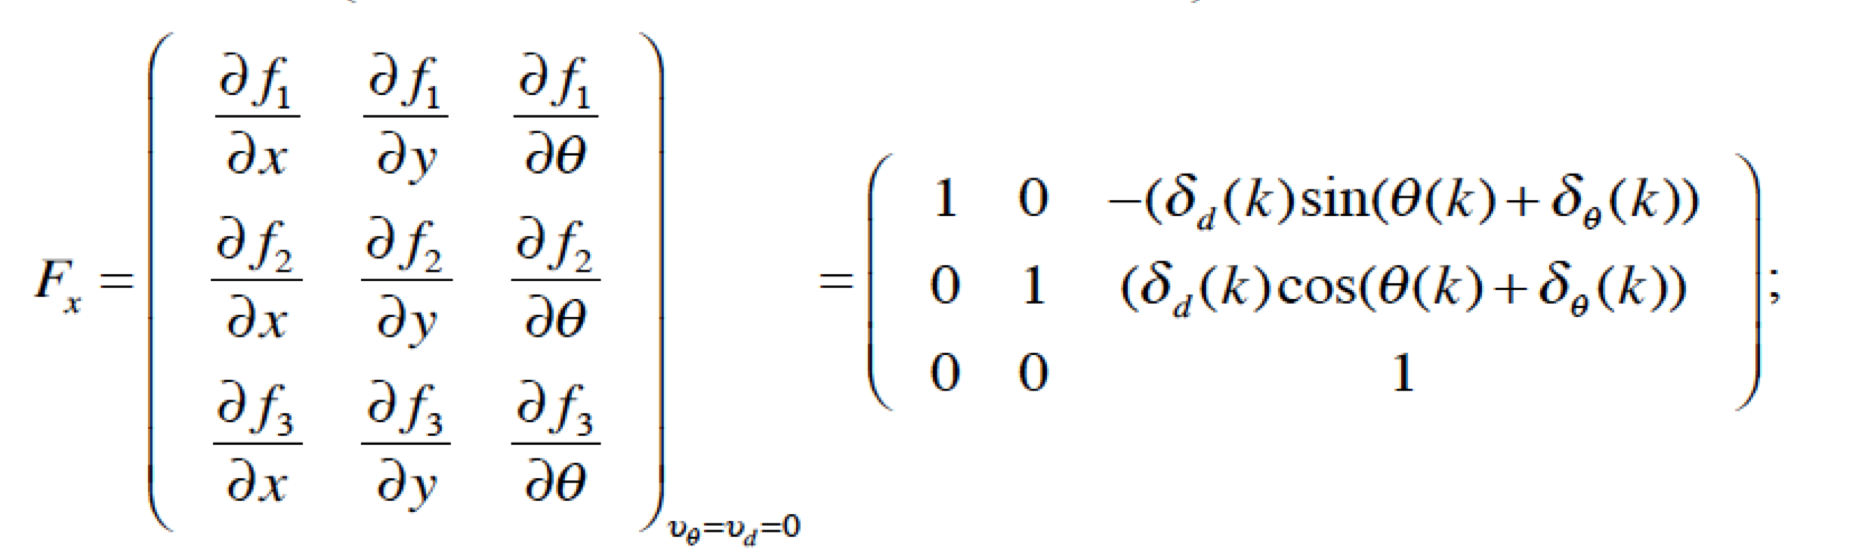

Jacobian evaluation

veh.Fx( [0,0,0], [0.5, 0.1] )% evaluate the Jacobian at pose [0 0 0] having odometry [0.5 0.1]

ans =     1.0000         0   -0.0499
         0    1.0000    0.4975
         0         0    1.0000


-0.5*sin(0+0.1)

ans = -0.0499

0.5*cos(0+0.1)

ans = 0.4975

Computing EKF

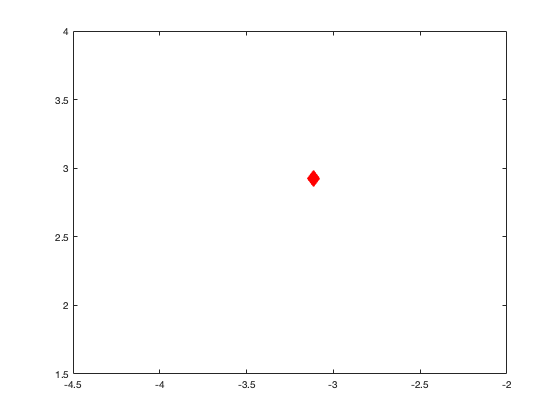

P0 = diag([0.005, 0.005, 0.001].^2); %Initial covariance matrix

ekf = EKF(veh, V, P0); % Create the ekf object which compute the pose stimation

randinit
ekf.run(1000);


clf
veh.plot_xy()

hold on
ekf.plot_xy('r')

P700 = ekf.history(700).P

P700 =     1.8557    0.6276    0.2297
    0.6276    1.6959    0.2095
    0.2297    0.2095    0.0533



sqrt(P700(1,1))

ans = 1.3623

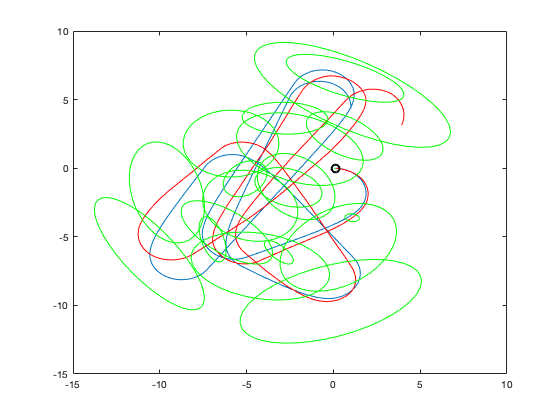


ekf.plot_ellipse('g')

##  Map-based localization

randinit % reset random number stream.

Build the Map with known landmarks position randonly distributed

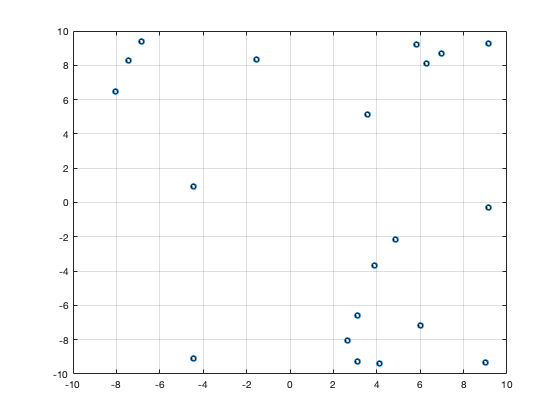

map = LandmarkMap(20, 10); %N = 20 landmarks uniformly randomly spread over a region spanning ±10 m

map.plot()
scatter(map.map(1,:), map.map(2,:))

### Sensor fusion

$z=h\left(x,p_i \right)$; $x=\left(x_v \;y_v \;\theta_v \right)$ is the vehicle state and $p_i =\left(x_i \;y_i \right)$is is the known location of the ith landmark in the world frame.

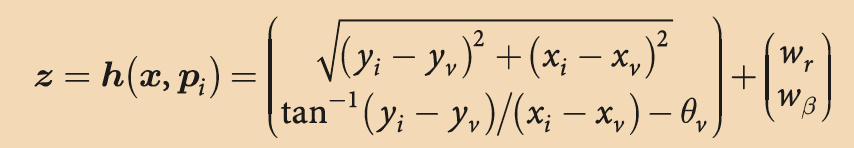

z = (r, β )' r is the distance to the landmark an β is bearing the robot see the landmark

w = (wr, wβ )T is a zero mean Gaussian random variable that models errors in the sensor

W = diag([0.1, 1*pi/180].^2); % Noise measurement

### Sensor on the vehiche

sensor = RangeBearingSensor(veh, map, 'covar', W)

sensor = 
RangeBearingSensor sensor class:
LandmarkMap object              
  20 landmarks                  
  dimension 10.0                
W = [0.01 0;0 0.000305]         
interval 1 samples              


Method reading. The landmark is chosen randomly from the set of visible landmarks. z = distance and bearing and i the Landmark ID


[z,i] = sensor.reading() % return distance and angle

z =    10.9664
   -1.0122


i = 19

map.landmark(17)

ans =    -4.4615
   -9.0766


randinit
map = LandmarkMap(20);
veh = Bicycle('covar', V);
veh.add_driver( RandomPath(map.dim) );

### Laser innovation & making the fusion

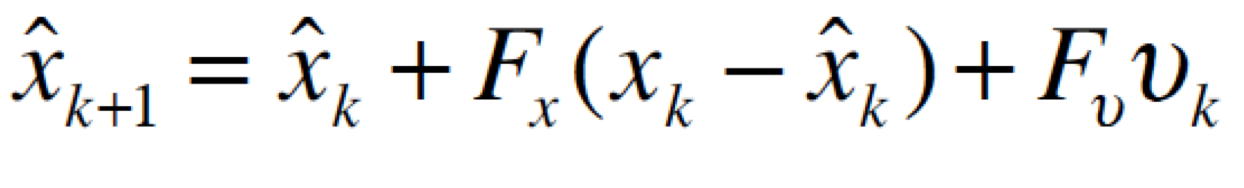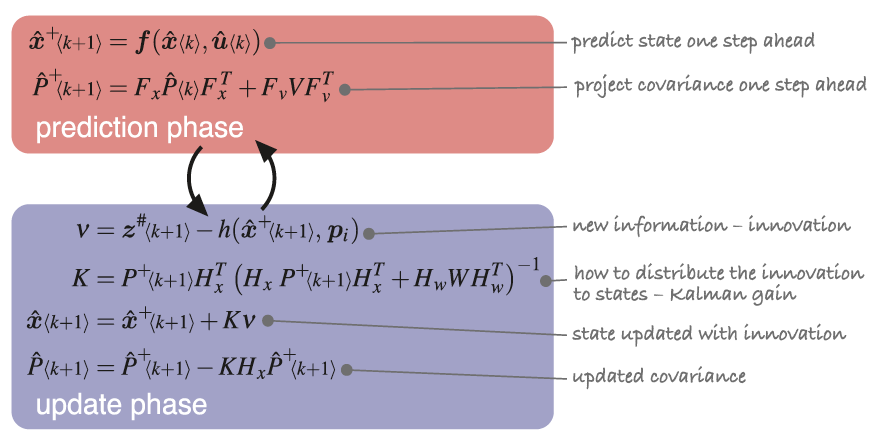

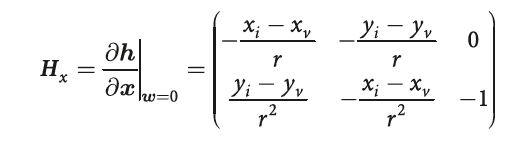

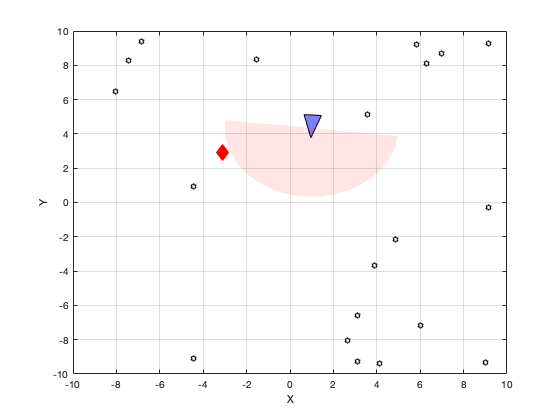

sensor = RangeBearingSensor(veh, map, 'covar', W, 'angle', ...
[-pi/2 pi/2], 'range', 4, 'animate');
ekf = EKF(veh, V, P0, sensor, W, map);

ekf.run(1000); % run the simulation be patient is running but there is no animation

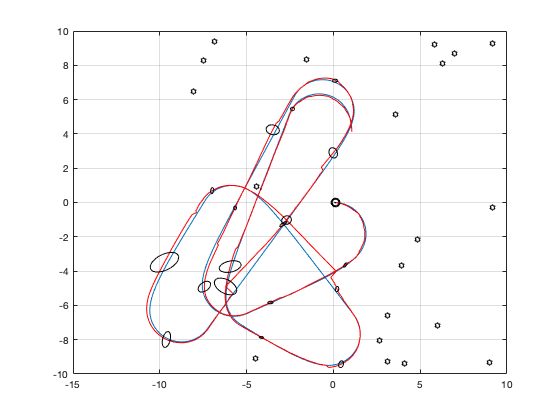

map.plot() % plot the map with the land marks
veh.plot_xy(); % Theoric trajectory
ekf.plot_xy('r'); % updated trajectory
ekf.plot_ellipse('k') % viasualizing the 2D ellipses

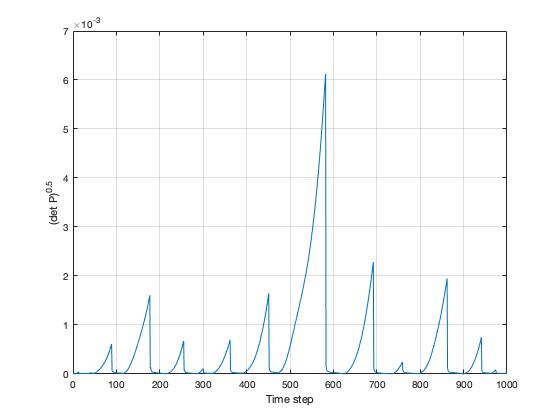

clf
ekf.plot_P() % compact way to see the coovariance 
xlabel('Time step'); ylabel('(det P)^{0.5}'); grid

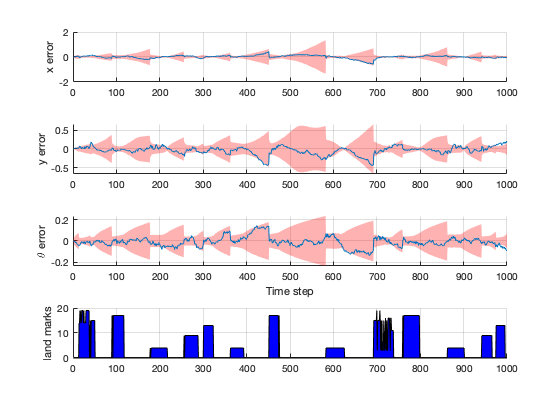


clf
ekf.plot_error('confidence', 0.95, 'nplots', 4) % errors x,y,theta  
plot_poly([1:1000; sensor.landmarklog], 'fill', 'b')% which landmark
ylabel('land marks')
grid